addpath('functions')

## Influence of the ceiling slope:

% Constants
c=343;              % Speed of Sound
roc=415;            % Characteristic Impedance of the air
pref2=4e-10;        % Squared reference for SPL
Wref=1e-12;         % Reference for Lw. 
Lw=90;              % Sound Power of the Source (in decibels)
W=Wref*10^(Lw/10);  % Sound power of the source in (watts)

### Case 1: Flat ceiling. 

% Dimensions.
H=7;    % Height 
Wide=7;  % Width
Length=20;    % Length 

% Points
 P1=[-Wide/2 0 H]; 
 P2=[Wide/2 0 H]; 
 P3=[Wide/2 Length H];
 P4=[-Wide/2 Length H];
 
Vertex=[P1;P2;P3;P4];
Faces=[ 1 2 3 4];

% Source
Sr=[0 0 0];

% Receivers
x=(-Wide/2:0.25:Wide/2);
y=(0:0.25:Length);
z=0;
[X,Y,Z]=meshgrid(x,y,z);
xyz=[X(1:end)' Y(1:end)' Z(1:end)'];

% Calculation:
EcPlano1=planec(Vertex);

Testing if all points belong to the plane
OK


IV1=fv(EcPlano1,Sr),

IV1 =      0     0    14


rd2=(Sr(1)-xyz(:,1)).^2+(Sr(2)-xyz(:,2)).^2+(Sr(3)-xyz(:,3)).^2; % Squared distance, direct ray distances. Common to all cases.
rr2=(IV1(1)-xyz(:,1)).^2+(IV1(2)-xyz(:,2)).^2+(IV1(3)-xyz(:,3)).^2;

Note: In this case all the receivers can see the IV. No visibility test is needed.

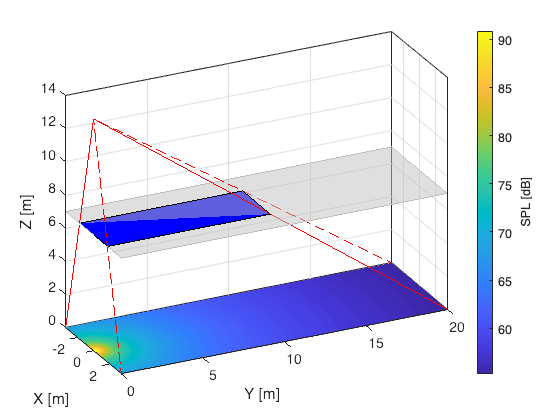


% SPL
pdir2=roc*W./(4*pi*rd2);
preflect2=roc*W./(4*pi*rr2);
pt=pdir2+preflect2;
SPLt=10*log10(pt/pref2);
low=min(SPLt); high=max(SPLt);
SPLt1=reshape(SPLt,size(X));

%% SHOWING RESULTS:
figure;
colores=[0.75 0.75 0.75].*ones(size(Vertex));
patch('Vertices', Vertex, 'Faces',Faces, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','flat');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
h=contourf(x,y,SPLt1,100,'EdgeColor','none'); box on;colorbar;
caxis([low high-10]);
h2 = colorbar; set(get(h2,'label'),'string','SPL [dB]');
axis equal; 

% Coberture region
C=[Vertex(:,1:2) zeros(4,1)];
rays=[IV1;C(1,:); IV1; C(2,:); IV1; C(3,:);IV1;C(4,:)];
coberture=line(rays(:,1),rays(:,2),rays(:,3));set(coberture,'Color','r','LineWidth',1,'LineStyle','--');
% Reflection area:

reflector=[intersecta(IV1,C(1,:),EcPlano1); intersecta(IV1,C(2,:),EcPlano1); intersecta(IV1,C(3,:),EcPlano1);intersecta(IV1,C(4,:),EcPlano1)];
fill3(reflector(:,1),reflector(:,2),reflector(:,3),'b');
hold off;
hold off;

### Case 2: Positive Slope

H2=3;
% Points
 P1=[-Wide/2 0 H2]; 
 P2=[Wide/2 0 H2]; 
 P3=[Wide/2 Length H];
 P4=[-Wide/2 Length H];
 
Vertex=[P1;P2;P3;P4];
Faces=[ 1 2 3 4];

% Source
Sr=[0 0 0];

% Calculation:
EcPlano2=planec(Vertex);

Testing if all points belong to the plane
OK


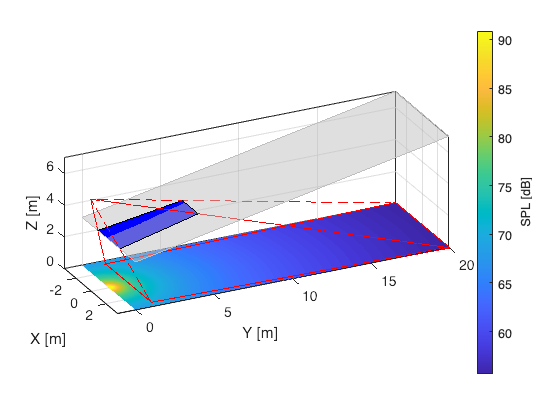

IV2=fv(EcPlano2,Sr);
M=length(xyz(:,1));
for ii=1:M
    aux=intersecta(IV2,xyz(ii,:),EcPlano2);
    IN(ii)=pip(aux,Vertex);
end
visibles=xyz(IN==1,:);
rr2=(IV2(1)-visibles(:,1)).^2+(IV2(2)-visibles(:,2)).^2+(IV2(3)-visibles(:,3)).^2;
pt2=zeros(size(X));

preflect2=roc*W./(4*pi*rr2);

pt=pdir2;
pt(IN==1)=pdir2(IN==1)+preflect2;
% SPL
SPLt=10*log10(pt/pref2);
low=min(SPLt); high=max(SPLt);
SPLt2=reshape(SPLt,size(X));

%% SHOWING RESULTS:
figure;
colores=[0.75 0.75 0.75].*ones(size(Vertex));
patch('Vertices', Vertex, 'Faces',Faces, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','flat');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
h=contourf(x,y,SPLt2,100,'EdgeColor','none'); box on;colorbar;
caxis([low high-10]);
h2 = colorbar; set(get(h2,'label'),'string','SPL [dB]');
axis equal;

% Coberture region:
C=[-3 min(visibles(:,2)) 0; 3 min(visibles(:,2)) 0; Vertex(3:4,1:2) zeros(2,1)];
fc=fill3(C(:,1),C(:,2),C(:,3),'r','FaceColor','none','EdgeColor','r','LineWidth',2);
rays=[IV2;C(1,:); IV2; C(2,:); IV2; C(3,:);IV2;C(4,:)];
coberture=line(rays(:,1),rays(:,2),rays(:,3));set(coberture,'Color','r','LineWidth',1,'LineStyle','--');
% Reflection area:
reflector=[intersecta(IV2,C(1,:),EcPlano2); intersecta(IV2,C(2,:),EcPlano2); intersecta(IV2,C(3,:),EcPlano2);intersecta(IV2,C(4,:),EcPlano2)];
fill3(reflector(:,1),reflector(:,2),reflector(:,3),'b');
hold off;

### Case 3: Negative Slope

% Points
 P1=[-Wide 0 H]; 
 P2=[Wide 0 H]; 
 P3=[Wide Length H2];
 P4=[-Wide Length H2];
 
Vertex=[P1;P2;P3;P4];
Faces=[ 1 2 3 4];


% Calculation:
EcPlano3=planec(Vertex);

Testing if all points belong to the plane
OK


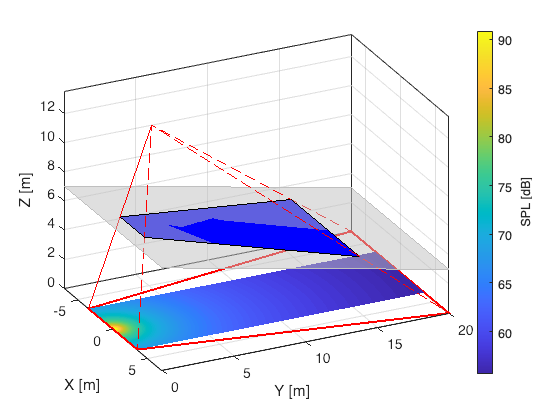

IV3=fv(EcPlano3,Sr);
M=length(xyz(:,1));
for ii=1:M
    aux=intersecta(IV3,xyz(ii,:),EcPlano3);
    IN(ii)=pip(aux,Vertex);
end
visibles=xyz(IN==1,:);

rr2=(IV3(1)-visibles(:,1)).^2+(IV3(2)-visibles(:,2)).^2+(IV3(3)-visibles(:,3)).^2;

preflect2=roc*W./(4*pi*rr2);

pt=pdir2;
pt(IN==1)=pdir2(IN==1)+preflect2;
% SPL
SPLt=10*log10(pt/pref2);
low=min(SPLt); high=max(SPLt);
SPLt3=reshape(SPLt,size(X));

%% SHOWING RESULTS:
figure;
colores=[0.75 0.75 0.75].*ones(size(Vertex));
patch('Vertices', Vertex, 'Faces',Faces, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','flat');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
h=contourf(x,y,SPLt3,100,'EdgeColor','none'); box on;colorbar;
caxis([low high-10]);
h2 = colorbar; set(get(h2,'label'),'string','SPL [dB]');
axis equal;

% Coberture region:
C=[-Wide/2 min(visibles(:,2)) 0; Wide/2 min(visibles(:,2)) 0; Vertex(3:4,1:2) zeros(2,1)];
fc=fill3(C(:,1),C(:,2),C(:,3),'r','FaceColor','none','EdgeColor','r','LineWidth',2);
rays=[IV3;C(1,:); IV3; C(2,:); IV3; C(3,:);IV3;C(4,:)];
coberture=line(rays(:,1),rays(:,2),rays(:,3));set(coberture,'Color','r','LineWidth',1,'LineStyle','--');
% Reflection area:
reflector=[intersecta(IV3,C(1,:),EcPlano3); intersecta(IV3,C(2,:),EcPlano3); intersecta(IV3,C(3,:),EcPlano3);intersecta(IV3,C(4,:),EcPlano3)];
fill3(reflector(:,1),reflector(:,2),reflector(:,3),'b');
hold off;

### Conclusions:

Let's compare the sound pressure level calculated in the three cases:

plot(y,SPLt1(X==0),y,SPLt2(X==0),y,SPLt3(X==0));
legend('Flat','Positive Slope','Negative Slope');grid; 

## Ceiling Design:  equipotential ceiling

- Geometry of the problem:

% Points
 Pr1=[-3 1 3]; 
 Pr2=[3 1 3]; 
 Pr3=[3 6 5];
 Pr4=[-3 6 5];
 
 Pr5=[3 11 6]; 
 Pr6=[-3 11 6]; 
 
 Pr7=[3 15 6]; 
 Pr8=[-3 15 6]; 
 
 Pr9=[3 23 5]; 
 Pr10=[-3 23 5]; 
 
 Pr11=[3 30 1]; 
 Pr12=[-3 30 1]; 
 
%  Pr7=[1 5 5];
%  Pr8=[-1 5 5];
%  Pr9=[-1 2 4]; 
%  Pr10=[1 2 4]; 
%  Pr11=[1 5 5];
%  Pr12=[-1 5 5];
%  Pr13=[-1 2 4]; 
%  Pr14=[1 2 4]; 
%  Pr15=[1 5 5];
%  Pr16=[-1 5 5];
 
Vertexr=[Pr1; Pr2; Pr3; Pr4;Pr5; Pr6; Pr7; Pr8; Pr9; Pr10; Pr11; Pr12];
Vertexr(:,3)=Vertexr(:,3)+4

Vertexr =     -3     1     7
     3     1     7
     3     6     9
    -3     6     9
     3    11    10
    -3    11    10
     3    15    10
    -3    15    10
     3    23     9
    -3    23     9


facesr= [1 2 3 4;
   3 5 6 4;
   5 7 8 6;
   7 9 10 8
   9 11 12 10];

Numberofsections=length(facesr(:,1));
colores=[0.75 0.75 0.75].*ones(length(Vertexr(:,1)),3);
% Source
Sr=[0 00 0];

% Receivers
x=(-15:0.25:15);
y=(0:0.25:30);
z=0;
[X,Y,Z]=meshgrid(x,y,z);
xyz=[X(1:end)' Y(1:end)' Z(1:end)'];


- Virtual Image Calculation:

EcPlanor=zeros(Numberofsections,4);
IV=zeros(Numberofsections,3);
for ii=1:Numberofsections
    EcPlanor(ii,:)=planec(Vertexr(facesr(ii,:),:));
    IV(ii,:)=fv(EcPlanor(ii,:),Sr);
end

Testing if all points belong to the plane
OK
Testing if all points belong to the plane
OK
Testing if all points belong to the plane
OK
Testing if all points belong to the plane
OK
Testing if all points belong to the plane
OK


- Detection of the recever points which can "see" the virtual image, i.e., those receiving a valid reflexion:

[M,N]=size(xyz);
intersecs=zeros(M,3,Numberofsections);
IN=zeros(M,Numberofsections);
for jj=1:Numberofsections
    for ii=1:M
        aux=intersecta(IV(jj,:),xyz(ii,:),EcPlanor(jj,:));
        IN(ii,jj)=pip(aux,Vertexr(facesr(jj,:),:));
    end
end


- Showing the results: 

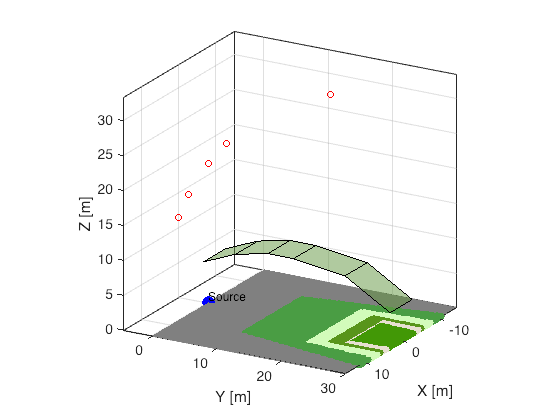

figure;
c=rand(3,1);
colores=[c(1)*ones(12,1) c(2)*ones(12,1) c(3)*ones(12,1) ];
patch('Vertices', Vertexr, 'Faces',facesr, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','k');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');

% Source:
plot3(Sr(1),Sr(2),Sr(3),'ob','MarkerFaceColor','b','MarkerSize',12);        % Source
text(0,0,1,'Source','FontSize',12);

% Receivers:
plot3(X,Y,Z,'Color',[0.5 0.5 0.5]);

% Virtual Image
plot3(IV(:,1),IV(:,2),IV(:,3),'or');
%text(IVr(1),IVr(2),IVr(3)+0.5,'Virtual Im','FontSize',12);
for ii=1:Numberofsections
    visibles=xyz(IN(:,ii)==1,:);
    c1=rand;c2=rand;c3=rand;
    plot3(visibles(:,1),visibles(:,2),visibles(:,3),'Marker',...
        'o','MarkerFaceColor',[c1 c2 c3],'Color',[c1 c2 c3],'MarkerSize',4);
end
view([120 20]);
axis equal; box on; hold off

- Sound Pressure Level: we consider a non coherent adition of the contributions.

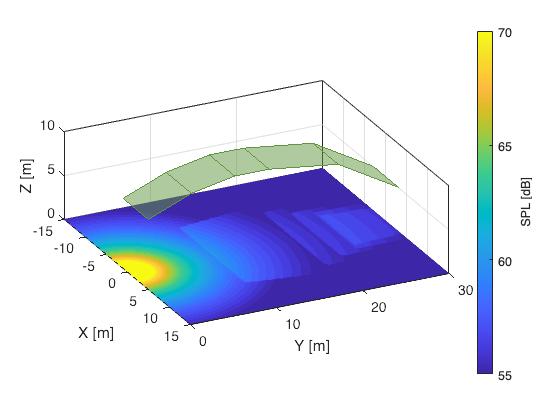


% Distances:

pt=zeros(length(xyz(:,1)),1);
aux=zeros(length(xyz(:,1)),Numberofsections);
rd2=(Sr(1)-xyz(:,1)).^2+(Sr(2)-xyz(:,2)).^2+(Sr(3)-xyz(:,3)).^2; % Squared distance between source and receivers

% Direct ray:
pdir2=roc*W./(4*pi*rd2);
for ii=1:Numberofsections
    visibles=xyz(IN(:,ii)==1,:);
    rr2=(IV(ii,1)-visibles(:,1)).^2+(IV(ii,2)-visibles(:,2)).^2+(IV(ii,3)-visibles(:,3)).^2; % Squared distance, reflected
    aux(IN(:,ii)==1,ii)=roc*W./(4*pi*rr2);
end
pt=pdir2+sum(aux,2);
SPLdir=10*log10(pdir2/pref2);
SPLt=10*log10(pt/pref2);
low=min(SPLt); high=max(SPLt);
SPLt=reshape(SPLt,size(X));
SPLdir=reshape(SPLdir,size(X));

%% SHOWING RESULTS:
figure;
patch('Vertices', Vertexr, 'Faces',facesr, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','flat');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
h=contourf(x,y,SPLt,100,'EdgeColor','none'); box on;colorbar;
caxis([55 70]);
h2 = colorbar; set(get(h2,'label'),'string','SPL [dB]');
axis equal; box on; 
hold off;

We can notice the increase of the sound pressure level:

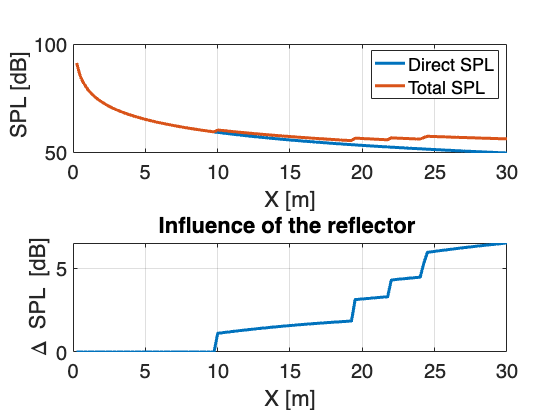

subplot(211);
plot(y,SPLdir(X==0),y,SPLt(X==0),'LineWidth',3); grid;
ylabel('SPL [dB]'); 
set(gca,'FontSize',20);xlabel('X [m]'); ylabel(' SPL [dB]'); 
legend('Direct SPL','Total SPL');
subplot(212),
plot(y,SPLt(X==0)-SPLdir(X==0),'LineWidth',3); grid; 
set(gca,'FontSize',20);xlabel('X [m]'); ylabel('\Delta SPL [dB]'); 
title('Influence of the reflector ')

## Fan Shape: 

- Geometry of the problem:

W1=10; % Half Width 
W2=10; % HAlf Width 
L=20;
% Points
 Pr1=[-W1  0 0]; 
 Pr2=[W1 0 0]; 
 Pr3=[W1 0 4];
 Pr4=[-W1 0 4];

 Pr5=[-W2  L 0]; 
 Pr6=[W2 L 0]; 
 Pr7=[W2 L 4];
 Pr8=[-W2 L 4];

 
Vertexr=[Pr1; Pr2; Pr3; Pr4;Pr5; Pr6; Pr7; Pr8];

facesr= [%1 2 3 4;  % Take care: counterclockwise looing from outside
    3 2 6 7;
%8 7 6 5;
1 4 8 5];

Numberofsections=length(facesr(:,1));
colores=[0.75 0.75 0.75].*ones(length(Vertexr(:,1)),3);
% Source
Sr=[0 0.5 1];

% Receivers
x=(-W2:0.2:W2);
y=(0:0.2:L);
z=0;
vertices=[Pr1;Pr2;Pr6;Pr5];
[X,Y,Z]=meshgrid(x,y,z);
xyz=[X(1:end)' Y(1:end)' Z(1:end)'];

in=inpolygon(xyz(:,1),xyz(:,2),vertices(:,1),vertices(:,2));
xyz=xyz(in,1:3);
tr=delaunay(xyz(:,1:2));
ind=find(xyz(:,1)==0);


- Virtual Image Calculation:

EcPlanor=zeros(Numberofsections,4);
IV=zeros(Numberofsections,3);
for ii=1:Numberofsections
    EcPlanor(ii,:)=planec(Vertexr(facesr(ii,:),:));
    IV(ii,:)=fv(EcPlanor(ii,:),Sr);
end

- Detection of the recever points which can "see" the virtual image, i.e., those receiving a valid reflexion:

[M,N]=size(xyz);
intersecs=zeros(M,3,Numberofsections);
IN=zeros(M,Numberofsections);
for jj=1:Numberofsections
    for ii=1:M
        aux=intersecta(IV(jj,:),xyz(ii,:),EcPlanor(jj,:));
        IN(ii,jj)=pip(aux,Vertexr(facesr(jj,:),:));
    end
end


- Showing the results: 

figure;
c=rand(3,1);
colores=[c(1)*ones(2,1) c(2)*ones(2,1) c(3)*ones(2,1) ];
patch('Vertices', Vertexr, 'Faces',facesr, 'FaceVertexCData', colores, 'FaceColor','flat','EdgeColor','k');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');

% Source:
plot3(Sr(1),Sr(2),Sr(3),'ob','MarkerFaceColor','b','MarkerSize',12);        % Source
text(0,0,1,'Source','FontSize',12);

% Receivers:
% plot3(X,Y,Z,'Color',[0.5 0.5 0.5]);

% Virtual Image
plot3(IV(:,1),IV(:,2),IV(:,3),'or','MarkerFaceColor','r','MarkerSize',12);
%text(IVr(1),IVr(2),IVr(3)+0.5,'Virtual Im','FontSize',12);
% for ii=1:Numberofsections
%     visibles=xyz(IN(:,ii)==1,:);
%     c1=rand;c2=rand;c3=rand;
%     plot3(visibles(:,1),visibles(:,2),visibles(:,3),'Marker',...
%         'o','MarkerFaceColor',[c1 c2 c3],'Color',[c1 c2 c3],'MarkerSize',4);
% end
view([120 20]);
axis equal; box on; 
hold off


- Sound Pressure Level: we consider a non coherent adition of the contributions.


% Distances:

pt=zeros(length(xyz(:,1)),1);
aux=zeros(length(xyz(:,1)),Numberofsections);
rd2=(Sr(1)-xyz(:,1)).^2+(Sr(2)-xyz(:,2)).^2+(Sr(3)-xyz(:,3)).^2; % Squared distance between source and receivers

% Direct ray:
pdir2=roc*W./(4*pi*rd2);
for ii=1:Numberofsections
    visibles=xyz(IN(:,ii)==1,:);
    rr2=(IV(ii,1)-visibles(:,1)).^2+(IV(ii,2)-visibles(:,2)).^2+(IV(ii,3)-visibles(:,3)).^2; % Squared distance, reflected
    aux(IN(:,ii)==1,ii)=roc*W./(4*pi*rr2);
end
pt=pdir2+sum(aux,2);
SPLdir=10*log10(pdir2/pref2);
SPLt=10*log10(pt/pref2);
low=min(SPLt); high=max(SPLt);


%% SHOWING RESULTS:
figure;
patch('Vertices', Vertexr, 'Faces',facesr,'FaceColor','b','EdgeColor','b');
alpha(0.5); view(64,24)                % Transparency 
grid on; hold on;
set(gca,'FontSize',14);xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
patch('Faces',tr,'Vertices',xyz,'FaceVertexCData',SPLt,'FaceColor','interp','EdgeColor','interp'); box on;colorbar;
caxis([50 80]);
h2 = colorbar; set(get(h2,'label'),'string','SPL [dB]');
axis equal; box on; plot3(IV(:,1),IV(:,2),IV(:,3),'or','MarkerFaceColor','r','MarkerSize',12);
hold off;

We can notice the increase of the sound pressure level:

subplot(211);
plot(y,SPLdir(ind),y,SPLt(ind),'LineWidth',3); grid;
ylabel('SPL [dB]'); 
set(gca,'FontSize',20);xlabel('X [m]'); ylabel(' SPL [dB]'); 
legend('Direct SPL','Total SPL');
subplot(212),
plot(y,SPLt(ind)-SPLdir(ind),'LineWidth',3); grid; 
set(gca,'FontSize',20);xlabel('X [m]'); ylabel('\Delta SPL [dB]'); 
title('Influence of the reflector ')